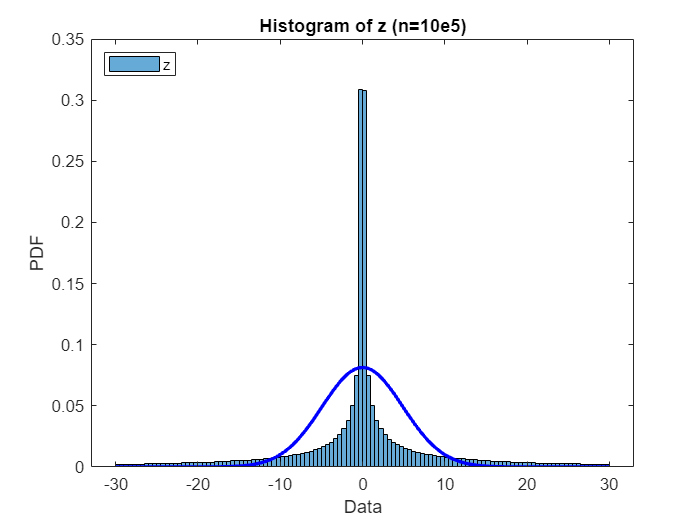

clear
clc
%parta

%forx
mu=0;
sigma=2;

%z=3x
mucalz=0;
sigmacalz=24;
% [muz, sigmaz]=affineGaussianTransform(mu,sigma,3,0)

% Generate a large number of samples from x
n=10e5;
x = normrnd(0, 2, 1, n);

% Calculate the corresponding values of z
z = x.^3;

% Compute the histogram of z
bins = -30:0.5:30; % Define the bins for the histogram
hist_z = histogram(z, bins, 'Normalization', 'pdf');

% Plot the theoretical PDF of z
z_pdf = normpdf(bins, 0, sqrt(24)); % Theoretical PDF of z
hold on % Add the histogram to the same plot
plot(bins, z_pdf, 'b-', 'LineWidth', 2)

% Add legend and axis labels
legend('z', 'Location', 'NorthWest')
xlabel('Data')
ylabel('PDF')
title('Histogram of z (n=10e5)')